# Solving Second order ODE with dirichlet BCs using Galerkin's Method.

Sagar Bodkhe

May 2020

__________________________________________________________________________________

In this example we are solving,

$\frac{d^2 u}{dx^2 }+f\left(x\right)=0\;\;$ in $x\in \left\lbrack 0\;L\right\rbrack$

Boundary conditions: $u\left(0\right)=u\left(L\right)=0$

We intend to find out $u\left(x\right)$such that boundary conditions are satisfied.

Declare the symbolic variable. **Note**: The argument of the function are automatically declared as symbolic variable.

close all;
clear all;

% Declare symbolic variable
syms u(x); % the state variable
syms f(x); % function in DE
syms As(i0,j0); % The Matrix A
syms bs(i0); % Matrix b
syms psi(x,i0); % basis functions
syms psidd(x,i0); % second derivative of basis functions
syms x
 assume(i0,'real')
assume(j0,'real')
assume(i0>0)
assume(j0>0)

Let us first find out the exact solution of the DE. We will use symbolic solver for this simple ODE.

% Define the function
f(x) = sin(x-x^2);


% Define the ODE
ode = diff(u,x,2) == -f;

% Boundary Conditions
L=4; % Length of the domain
cond1 = u(0) == 0;
cond2 = u(L) == 0;
conds = [cond1 cond2];
uSol = dsolve(ode,conds);
uSol = simplify(uSol);

% Convert the symbolic function to numerical function
uSol = matlabFunction(uSol);

Let us choose the dimesion of the trial space (same as the number of basis functions to be used) and select the basis function. The basis function should satisfy the essential boundary conditions.

N=6 ;% Dimension of trial space


% Generate Basis Functions and required derivative


The basis functions that we are choosing are: 

##  $\psi_i =x^i \left(x-L\right)$. 

Note that all of them satisfy essential BCs.

The other matrices/vectors :

## 
$$b_i =-\int_0^L f\left(x\right)$$

$$\psi_i \;\;\mathrm{dx}$$


## 
$$A_{\mathrm{ij}} =$$

$$\int_0^L \psi_i \;{\psi_j }^{\mathrm{''}} \;\mathrm{dx}$$


psi(x,i0)= (x^i0*(x-L)); % Basis functions 
psidd(x,i0) = (diff(psi,x,2)); % Second derivatives

bs(i0) = int(-f*psi(x,i0),x,[0 L]); %
As(i0,j0) = int(psi(x,i0)*psidd(x,j0),x,[0 L]);

The above symbolic functions are single functions of i and j.

Now, let us generate the **A **and **b** matrices using nested for loop over **i** and **j**

A = zeros(N,N);
b = zeros(N,1);
 for i1=1:N
     for j1=1:N
        A(i1,j1)=double(As(i1,j1)); 
        % double used to convert to number from symbolic variable
     end
     b(i1) = double(bs(i1));
 end
 

Solving for the N coefficients (c)  $c=A^{-1} b$


% The coeff vector for system
c=A\b; 


We now have the c. We just need to plug-in the c into the appozimate solution that we constructed:

## 
$$u_h \left(x\right)=\sum_i c_{i\;} \psi_i \left(x\right)$$


For this let us first transform the **psi** and **psidd** symbolic function to a matlab function of two variables.

psi = matlabFunction(psi);
psidd = matlabFunction(psidd);

divs=100; % Number of divisions for domain for plotting
X = linspace(0,L,divs); % Define the domain

ps = zeros(divs,N);
psdd = zeros(divs,N); 
% Matrix whose each column contain value of a basis function/derivative over the domain

for i2=1:N    
    ps(:,i2) = psi(X,i2);   
    psdd(:,i2) = psidd(X,i2);
end

psdd(isnan(psdd))=psdd(2,1); % Correction for 0 to the power 0


U= c'*ps'; % Trial Soltution
R= c'*psdd' + double(f(X));
R=round(R,7);


Let's plot the results now.

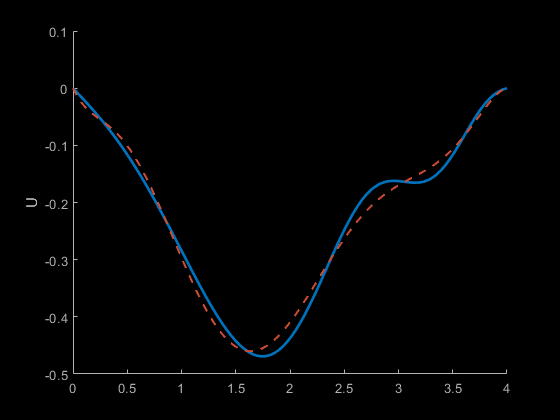

% Ploting Actual Solution and Trial solution
figure(1)
clf
hold on;
plot(X,uSol(X),"Linewidth",2)
plot(X,U,'--',"Color",[0.8 0.3 0.2],"Linewidth",1.5)
ylabel("U")

blackFig;

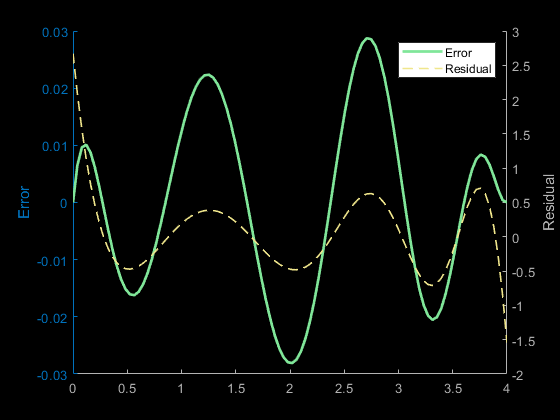


% Plotting Error
figure(2)
clf
hold on;

yyaxis left
ylabel("Error")
plot(X,round((uSol(X)-U),7),'-',"Linewidth",2,"Color",[0.5 0.9 0.6])

yyaxis right
ylabel("Residual")
plot(X,R,'--',"Linewidth",1.2,"Color",[ 0.9412 0.9020 0.5490]);
legend("Error","Residual")

blackFig;